# Classify human electrocardiogram (ECG) Signals

Given is the following ECG signal

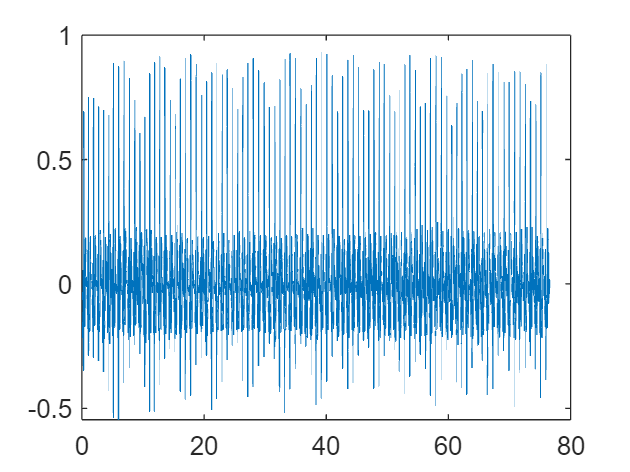

close all
clear all
% load ecg signal 
ecg =load('ecg.mat');
% Graphical Output
% Time Signal
t = [0:length(ecg.data)-1]/ecg.fs;
plot(t,ecg.data)

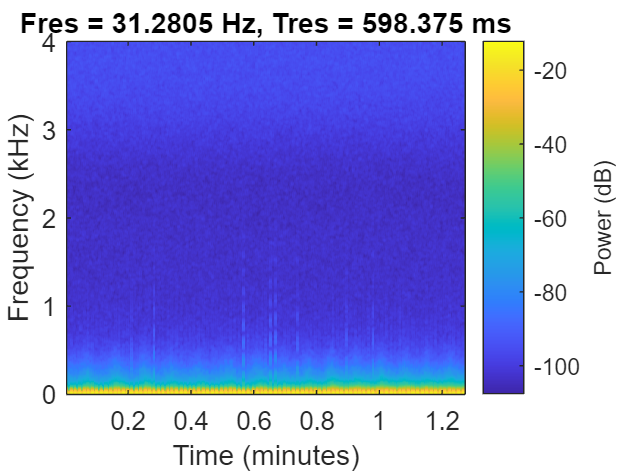

% Short Time Fourier Analysis -- Spectrogram
pspectrum(ecg.data,ecg.fs,'spectrogram')

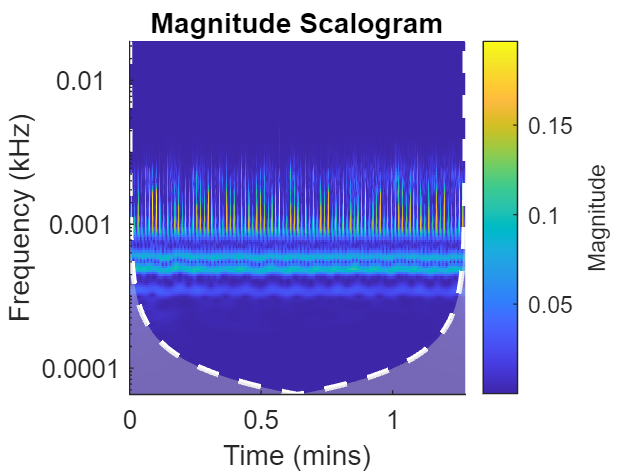

% Wavelet Analysis -- Scalogram
cwt(ecg.data,[],ecg.fs)

In general people can be devided in three groups:

- persons with cardiac arrhythmia (ARR)

- persons with congestive heart failure (CHF), and

- persons with normal sinus rhythms (NSR). 

The goal of this PStA is to classify human electrocardiogram (ECG) signals using the Short Time Fourier Transformation and the Continuous Wavelet Transform (CWT) and deep convolutional neural networks (CNNs). The resulting CNNs shall be used to classify the given ECG signal to ARR, CHF, and NSR, respectively. 

### Matlab Example

The Matlab Example [Classify Time Series Using Wavelet Analysis and Deep Learning - MATLAB & Simulink Example - MathWorks Deutschland](https://de.mathworks.com/help/releases/R2020b/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html) can be taken as a basis. It uses ECG data (the training and test data are publicly available from [PhysioNet](https://physionet.org/)) obtained from three groups of people: persons with cardiac arrhythmia (ARR), persons with congestive heart failure (CHF), and persons with normal sinus rhythms (NSR). In total  162 ECG recordings from three PhysioNet databases are used: [MIT-BIH Arrhythmia Database](https://www.physionet.org/physiobank/database/mitdb/) , [MIT-BIH Normal Sinus Rhythm Database](https://www.physionet.org/physiobank/database/nsrdb/) , and [The BIDMC Congestive Heart Failure Database](https://www.physionet.org/physiobank/database/chfdb/); more specifically, 96 recordings from persons with arrhythmia, 30 recordings from persons with congestive heart failure, and 36 recordings from persons with normal sinus rhythms. Two deep CNNs, GoogLeNet and SqueezeNet, pretrained for image recognition, are adapted to classify ECG waveforms based on a time-frequency representation -- the Wavelet Transformation.

## Tasks

- Complete the Live Script

- Dokument and explain your code with theoretical background -- detailed and understandable -- within the Live Script. Use additional plottings.

- Dokumentation and transparent coding has an important impact on the mark!

- Use the following time-frequency representations and investigate the impact on the ECG classification: Short Time Fourier Transformation and Wavelet Transformation

- Use the following pretrained deep CNNs and compare the results for the ECG classification; GoogLeNet, SqueezeNet and AlexNet.

## Data Preprocessing & Datastore

Generate the time-frequency representation using

- Short Time Fourier Transformation and

- Wavelet Transformation

and generate the corresponding data stores.

Compare the impact on the CNNs by comparing the confusion charts!

**1. First step is to download the data from PhysioNet's and use it to produce the time frequency representation and to train our network.**

Create the path to  the data 

clear('tempdir')
setenv('tmp','C:\Users\avadh\Desktop\new dsp\')%Put your path here
tempdir

ans = 'C:\Users\avadh\Desktop\new dsp\'

**2. Unzip the downloaded data and Load the data file into the MATLAB workspace.**

unzip(fullfile(tempdir,'physionet_ECG_data-main.zip'),tempdir)
load(fullfile(tempdir,'ECGData.mat'))


**3. Store the preprossed data of each category **

**    helperCreateECGDataDirectories**

parentDir1 = tempdir;
dataDir1 = 'Scalograms';
helperCreateECGDirectories(ECGData,parentDir1,dataDir1)

parentDir2 = tempdir;
dataDir2 = 'Spectograms';
helperCreateECGDirectories(ECGData,parentDir2,dataDir2)

** Plot a representative of each ECG category**

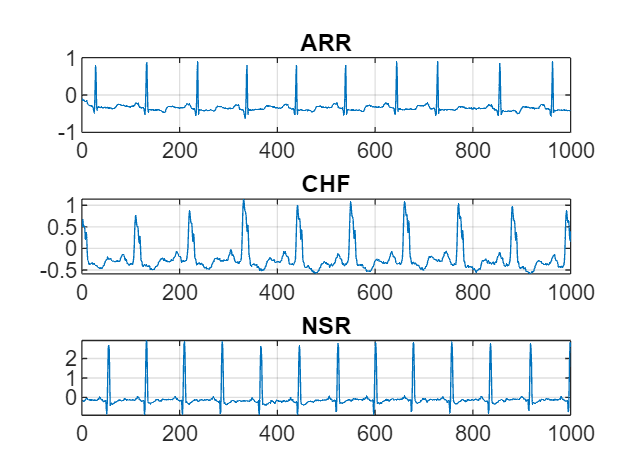

helperPlotReps(ECGData)

## **4. Create Time-Frequency Representations**

The input data for the proposed 2D-CNN must be of the image type. As a result, the time-domain ECG signals from three groups of subjects were first converted into 2D time-frequency spectrograms using the Short-time Fourier Transform (STFT) and Wavelet Transform.

# 1-Wavelet Transformation 

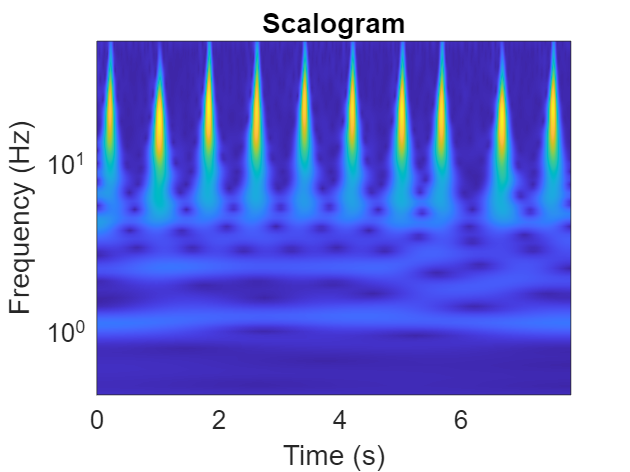

Fs = 128;
fb = cwtfilterbank('SignalLength',1000,...
    'SamplingFrequency',Fs,...
    'VoicesPerOctave',12);
sig = ECGData.Data(1,1:1000);
[cfs,frq] = wt(fb,sig);
t = (0:999)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)')

### Creats the scalograms as RGB images  

To be compatible with the pre-trained Networks architecture, we create the scalograms as RGB images. Each RGB image is an array with the dimensions 224x224x3. 

**HelperCreateRGBfromTF**

helperCreateRGBfromTF(ECGData,parentDir1,dataDir1)

# 2-Short Time Fourier Transformation

The STFT is an enhanced mathematical methodology, derived from the discrete Fourier transform (DFT), to explore the instantaneous frequency as well as the instantaneous amplitude of localized waves with timevarying characteristics.

For a discretized digital signal, its time-frequency spectrogram is given as:

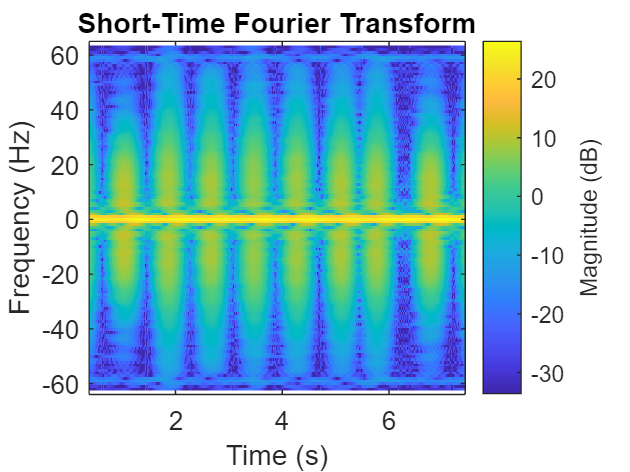

Fs=126;
win = hamming(100,'periodic');
stft(ECGData.Data(1,1:1000),Fs,'Window',win,'OverlapLength',98,'FFTLength',128);

xlim([0.38 7.43])
ylim([-64 65])

**helperCreateRGBfromTFS**

Also, built as RGB images to be compatible with pre-trained network architectures, each RGB image is an array of size 224×224×3

helperCreateRGBfromSTF(ECGData,parentDir2,dataDir2)

### **Divide Scalograms Images into Training and Validation Data**

The [`imageDatastore`](https://de.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) function automatically labels the images based on folder names and stores the data as an ImageDatastore object

allImages1 = imageDatastore(fullfile(parentDir1,dataDir1),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

Randomly we divided the images into two groups, one for training and the other for validation. 

Set  80% of the images for training, and the rest for validation. For purposes of reproducibility.

rng default
[imgsTrain1,imgsValidation1] = splitEachLabel(allImages1,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain1.Files))]);

Number of training images: 130


disp(['Number of validation images: ',num2str(numel(imgsValidation1.Files))]);

Number of validation images: 32


### **Divide Scalograms Images into Training and Validation Data**

allImages2 = imageDatastore(fullfile(parentDir2,dataDir2),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

Randomly we divided the images into two groups, one for training and the other for validation. 

Then, set  80% of the images for training, and the remainder for validation. For purposes of reproducibility.

rng default
[imgsTrain2,imgsValidation2] = splitEachLabel(allImages2,0.8,'randomized');
disp(['Number of training images(Spectograms): ',num2str(numel(imgsTrain2.Files))]);

Number of training images(Spectograms): 130


disp(['Number of validation images(Spectograms): ',num2str(numel(imgsValidation2.Files))]);

Number of validation images(Spectograms): 32


## Design CNNs

For the CNNs the following pretrained networks shall be used: GooLeNet, SqueezeNet and AlexNet. Adopt the networks to the ECG classification.

### GoogLeNet (`net1 = googlenet)`

`1-`Extracting and displaying the layer graph from the network.

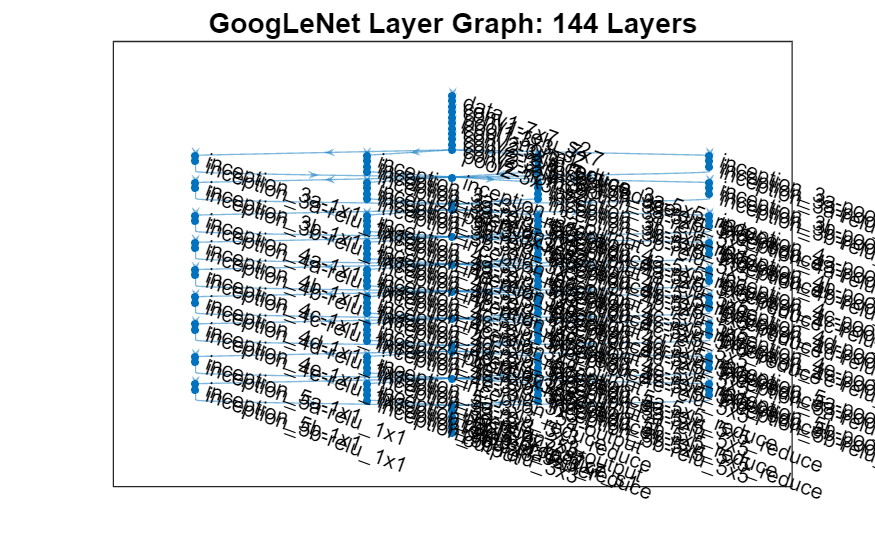

net1 = googlenet;

lgraphGN = layerGraph(net1);
numberOfLayers = numel(lgraphGN.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraphGN)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

**2**-Inspecting the first element of the network Layers property to confirm that the images of size 224x224x3 have created.

net1.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


**3-**Modify GoogLeNet Network Parameters

To prevent overfitting, a dropout layer is used. A dropout layer randomly sets input elements to zero with a given probability.

The default probability is 0.5. Replace the final dropout layer in the network, `'pool5-drop_7x7_s1'`, with a dropout layer of probability 0.6.

newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraphGN = replaceLayer(lgraphGN,'pool5-drop_7x7_s1',newDropoutLayer);

Replace the fully connected layer "loss3-classifier" with a new fully connected layer with the number of filters equal to the number of classes.

numClasses = numel(categories(imgsTrain1.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraphGN = replaceLayer(lgraphGN,'loss3-classifier',newConnectedLayer);

The classification layer specifies the output classes of the network. We replace the classification layer with a new one without class labels. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraphGN = replaceLayer(lgraphGN,'output',newClassLayer);

### SqueezeNet (net2` = squeezenet`)

### The second network model SqueezeNet (net2 = squeezenet)

net2 = squeezenet;

Extract the layer graph from the network. Also we confirm that SqueezeNet is configured for images of size 227x227x3.

lgraphSqz = layerGraph(net2);
disp(['Number of Layers: ',num2str(numel(lgraphSqz.Layers))])

Number of Layers: 68


disp(lgraphSqz.Layers(1).InputSize)

   227   227     3



**Modify SqueezeNet Network Parameters**

Inspect the last six network layers.

lgraphSqz.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                      50% dropout
     2   'conv10'                            2-D Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                         ReLU
     4   'pool10'                            2-D Global Average Pooling   2-D global average pooling
     5   'prob'                              Softmax                      softmax
     6   'ClassificationLayer_predictions'   Classification Output        crossentropyex with 'tench' and 999 other classes

Replace the `'drop9'` layer, the last dropout layer in the network, with a dropout layer of probability 0.6.

tmpLayer = lgraphSqz.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newDropoutLayer);

The last learnable layer in SqueezeNet is a 1-by-1 convolutional layer, `'conv10'`, and not a fully connected layer .Therefore replace the `'conv10'` layer with a new convolutional layer with the number of filters equal to the number of classes

numClasses = numel(categories(imgsTrain1.Labels));
tmpLayer = lgraphSqz.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newLearnableLayer);

Now Inspect the last six layers of the network and confirm the dropout, convolutional, and output layers have been changed.

tmpLayer = lgraphSqz.Layers(end);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newClassLayer);

**Prepare RGB Data for SqueezeNet and AlexNet**

augimgsTrain1 = augmentedImageDatastore([227 227],imgsTrain1);
augimgsValidation1 = augmentedImageDatastore([227 227],imgsValidation1);

lgraphSqz.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                      60% dropout
     2   'new_conv'          2-D Convolution              3 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                         ReLU
     4   'pool10'            2-D Global Average Pooling   2-D global average pooling
     5   'prob'              Softmax                      softmax
     6   'new_classoutput'   Classification Output        crossentropyex

### AlexNet (net3 = alexnet)

net3 = alexnet; 
layersTransfer = net3.Layers;%preserving all layers 
lgraphAlx = layerGraph(layersTransfer);
disp(['Number of Layers: ',num2str(numel(lgraphAlx.Layers))])

Number of Layers: 25


disp(lgraphAlx.Layers(1).InputSize)

   227   227     3



**Modify AlexNet Network Parameters**

like GoogLeNet

Inspect  network layers.

lgraphAlx.Layers()

ans =   25×1 Layer array with layers:

     1   'data'          Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'         2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'         ReLU                          ReLU
     4   'norm1'         Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'         2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'         2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'         ReLU                          ReLU
     8   'norm2'         Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'         2-D Max Pooling               3×3 max po

Replace the `'drop7'` layer, the last dropout layer in the network, with a dropout layer of probability 0.6.

tmpLayer = lgraphAlx.Layers(22);
newDropoutLayer = dropoutLayer(0.6,'Name','New_dropout');
lgraphAlx = replaceLayer(lgraphAlx,tmpLayer.Name,newDropoutLayer);

Replace the fully connected layer `'fc8'` with a new fully connected layer with the number of filters equal to the number of classes. 

numClasses = numel(categories(imgsTrain1.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraphAlx = replaceLayer(lgraphAlx,'fc8',newConnectedLayer);

The classification layer specifies the output classes of the network. We replace the classification layer with a new one without class labels. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraphAlx = replaceLayer(lgraphAlx,'output',newClassLayer);

Inspect the last Four Network's layers to make sure that layers have been changed 

lgraphAlx.Layers(end-3:end)

ans =   4×1 Layer array with layers:

     1   'New_dropout'       Dropout                 60% dropout
     2   'new_fc'            Fully Connected         3 fully connected layer
     3   'prob'              Softmax                 softmax
     4   'new_classoutput'   Classification Output   crossentropyex

## Train the Networks

## Wavelet Transformation Representation Data

## 1-GoogleNet

**1.1Training Options and Train the Network**

Training can be tuned by setting various options. `InitialLearnRate` specifies the initial step size in the direction of the negative gradient of the loss function. `MiniBatchSize` specifies how large of a subset of the training set to use in each iteration. One epoch is a full pass of the training algorithm over the entire training set. `MaxEpochs` specifies the maximum number of epochs to use for training. After trying many values of number of epochs the bast value will that generate good model without overfitting and underfitting will be 10 epochs.

options1 = trainingOptions('sgdm',...
    'MiniBatchSize',10,...
    'MaxEpochs',13,...
    'InitialLearnRate',0.0001,...
    'ValidationData',imgsValidation1,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Train the Network

trainedGN = trainNetwork(imgsTrain1,lgraphGN,options1);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:25 |       30.00% |       46.88% |       2.1278 |       1.2245 |      1.0000e-04 |
|       1 |          10 |       00:01:23 |       50.00% |       71.88% |       1.7229 |       0.8847 |      1.0000e-04 |
|       2 |          20 |       00:02:20 |       70.00% |       62.50% |       0.7111 |       0.6813 |      1.0000e-04 |
|       3 |          30 |       00:03:07 |       60.00% |       71.88% |       0.9317 |       0.4753 |      1.0000

trainedGN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**1.2- Evaluate GoogLeNet **

**1.2.1 Network  Accuracy**

Evaluate the network using the validation data(model testing)

[YPred1,probs1] = classify(trainedGN,imgsValidation1);
accuracy = mean(YPred1==imgsValidation1.Labels);
disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%'])

GoogLeNet Accuracy: 96.875%


Display four sample validation images with their predicted labels.

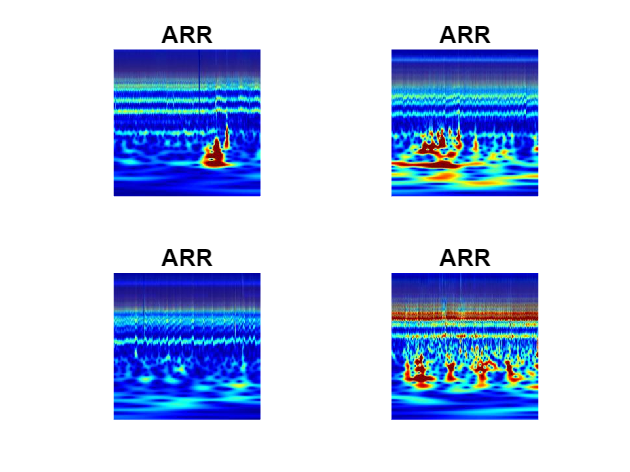

%idx = randperm(numel(imgsValidation.Files),4);
idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation1,idx(i));
    imshow(I)
    label = YPred1(idx(i));
    title(string(label));
end

## **2-SqueezeNet**

**2.1 Training Options and Train **

ilr = 3e-4;
miniBatchSize = 10;
maxEpochs = 18;
valFreq = floor(numel(augimgsTrain1.Files)/miniBatchSize);
options2 = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',0.0001,...
    'ValidationData',augimgsValidation1,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default

Network training

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       20.00% |       43.75% |       4.2000 |       1.8320 |      1.0000e-04 |
|       1 |          10 |       00:00:38 |       70.00% |       53.12% |       0.7981 |       0.9543 |      1.0000e-04 |
|       2 |          20 |       00:01:01 |       50.00% |       71.88% |       0.9528 |       0.8482 |      1.0000e-04 |
|       3 |          30 |       00:01:37 |       60.00% |       71.88% |       0.9320 |       0.7724 |      1.0000

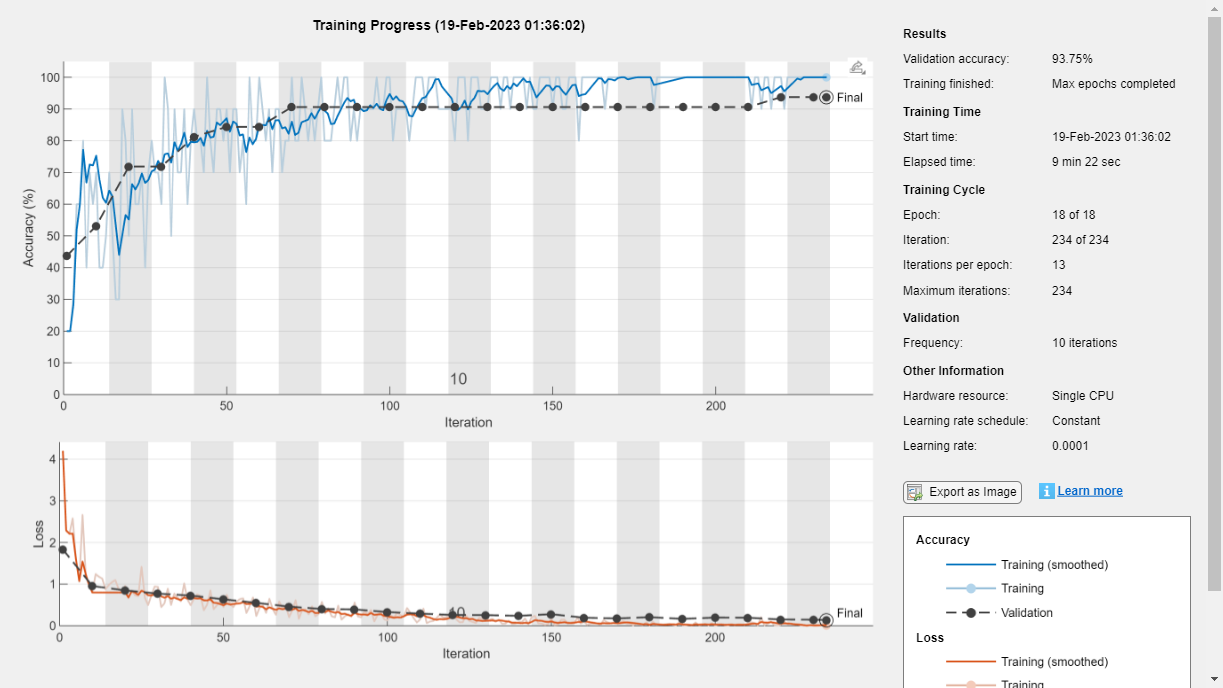

trainedSN = trainNetwork(augimgsTrain1,lgraphSqz,options2);

trainedSN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**2.2 Evaluate SqueezeNet Accuracy**

Evaluate the network using the validation data.

[YPred2,probs2] = classify(trainedSN,augimgsValidation1);
accuracy = mean(YPred2==imgsValidation1.Labels);
disp(['SqueezeNet Accuracy: ',num2str(100*accuracy),'%'])

SqueezeNet Accuracy: 93.75%


Display four sample validation images with their predicted labels

idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation1,idx(i));
    imshow(I)
    label = YPred2(idx(i));
    title(string(label));
end

## 3-AlexNet

**3.1 Training Options and Train AlexNet**

Training parameter settings

options3 = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',15, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimgsValidation1, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the Network

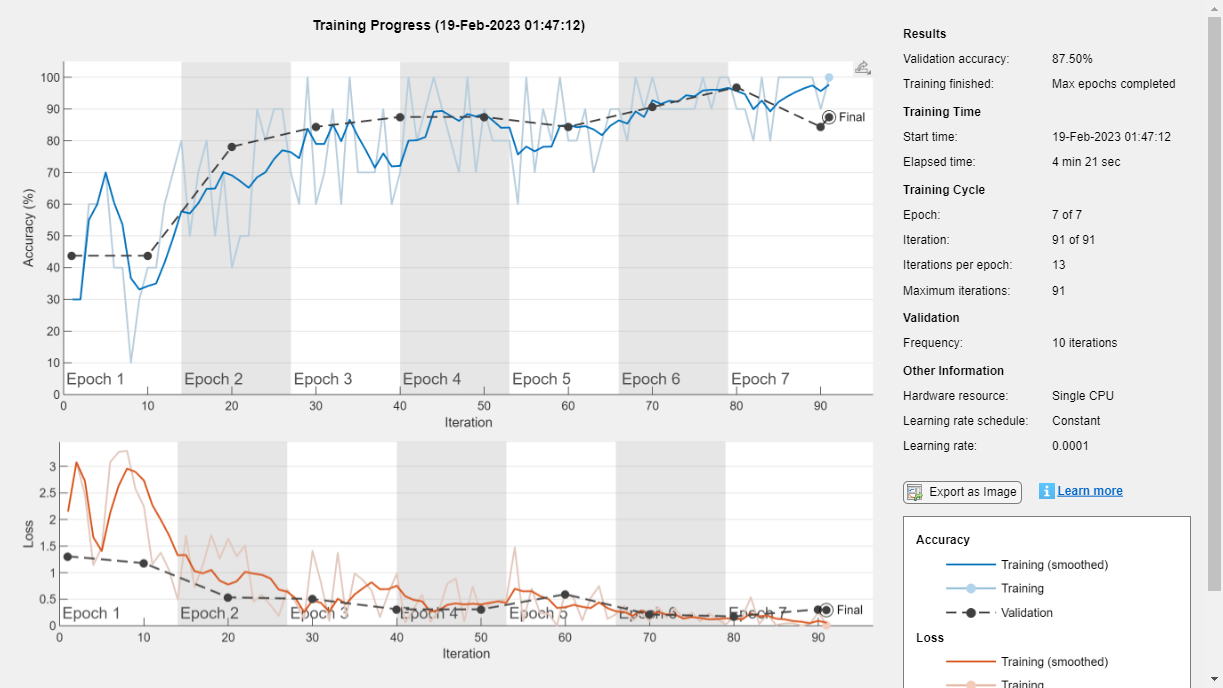

netTransfer1 = trainNetwork(augimgsTrain1,lgraphAlx,options3);

netTransfer1.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**3.3 Evaluate AlexNet Accuracy**

[YPred3,probs3] = classify(netTransfer1,augimgsValidation1);
accuracy = mean(YPred3==imgsValidation1.Labels);
disp(['ALexNet Accuracy: ',num2str(100*accuracy),'%'])

ALexNet Accuracy: 87.5%


Display four sample validation images with their predicted labels

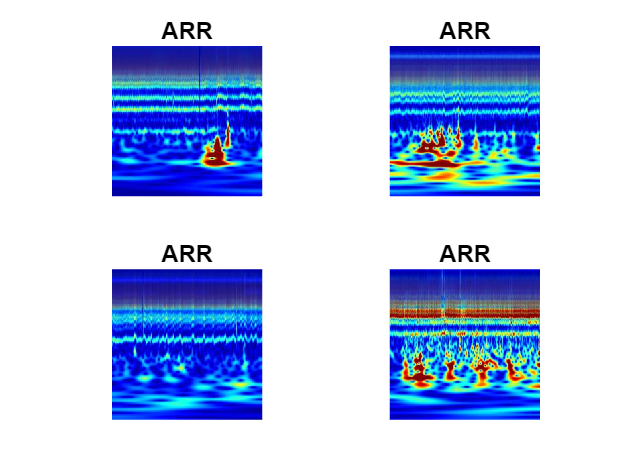

idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation1,idx(i));
    imshow(I)
    label = YPred3(idx(i));
    title(string(label));
end

## Test and validate the Networks -- Confusion Charts

Compare the results and the reliabilty of the different Time and Frequency Representations and the different Networks. Explain the differences!

## Confusion Charts (Wavelet Transformation Representation)

#### GoogleNet Confusion Chart

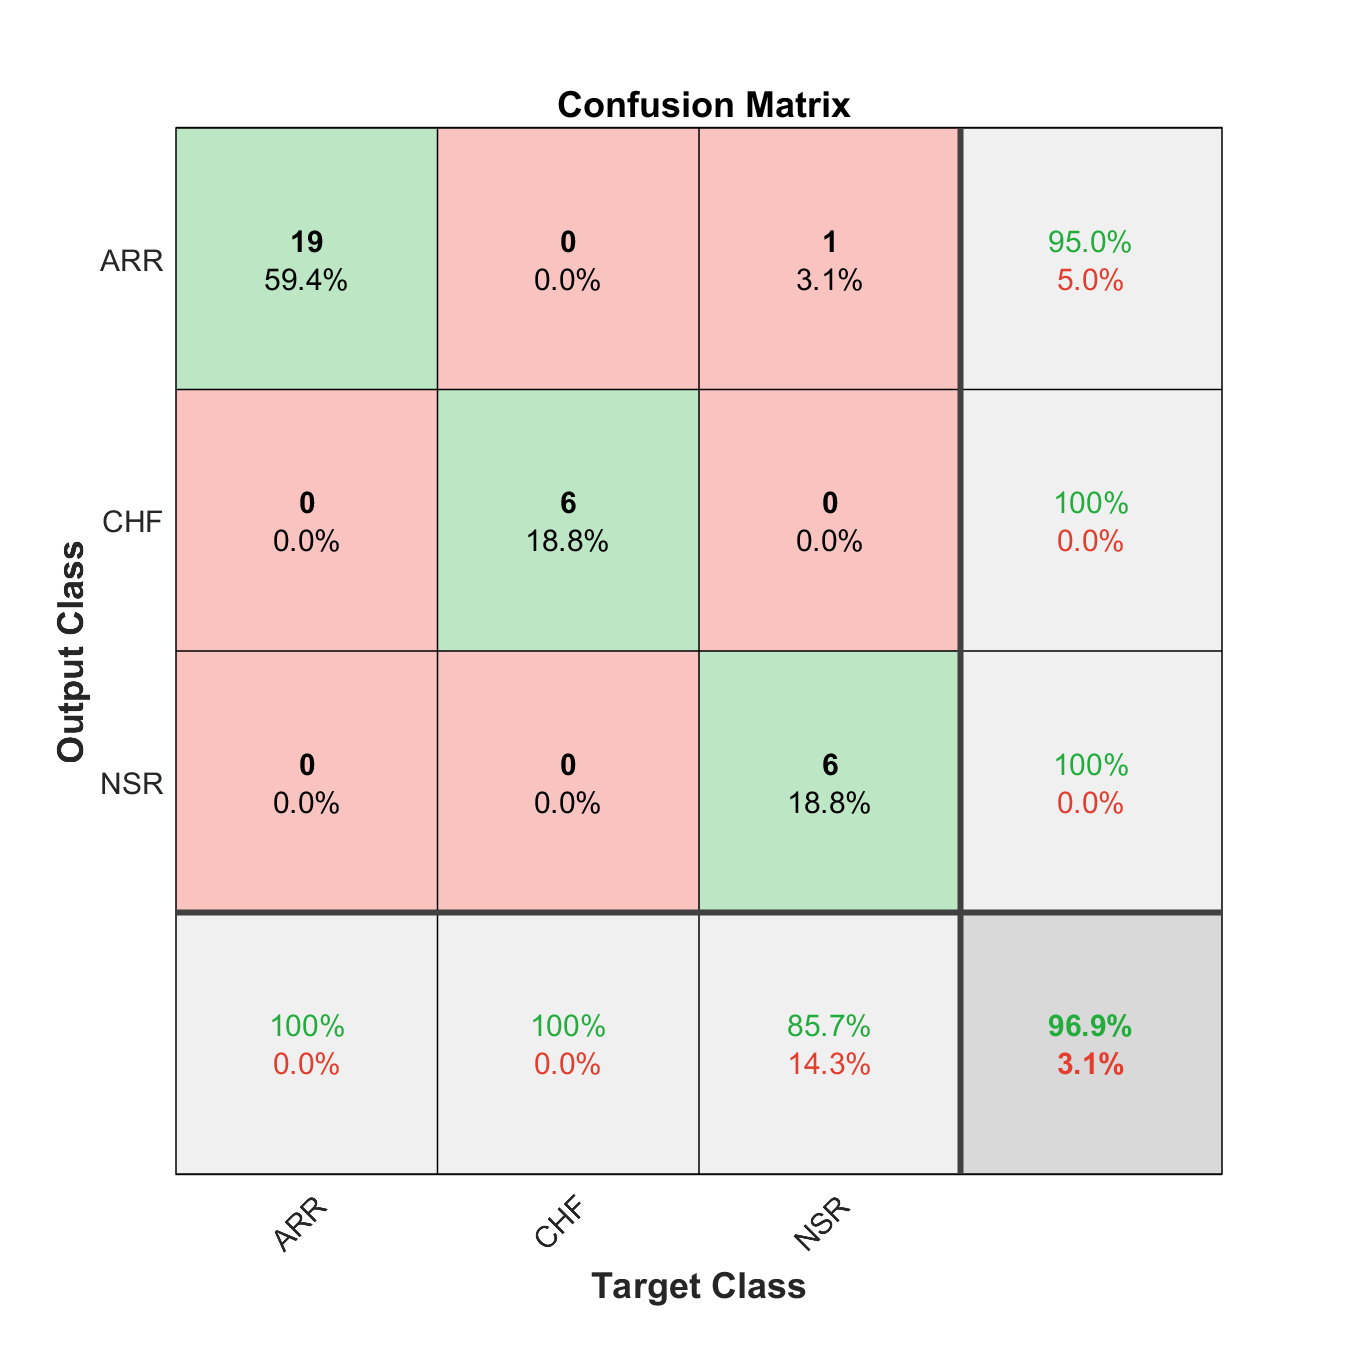

plotconfusion(imgsValidation1.Labels,YPred1)

The confusion matrix shows the relation between the output class and the target class regarding classification and misclassifications. For example, in ARR, we see that out of 20 testing images, 19 are correctly classified, 1 are misclassified as NSR. On the other hand, for CHF and NSR, 6 images are correctly classified.

#### SqueezNet Confusion Chart

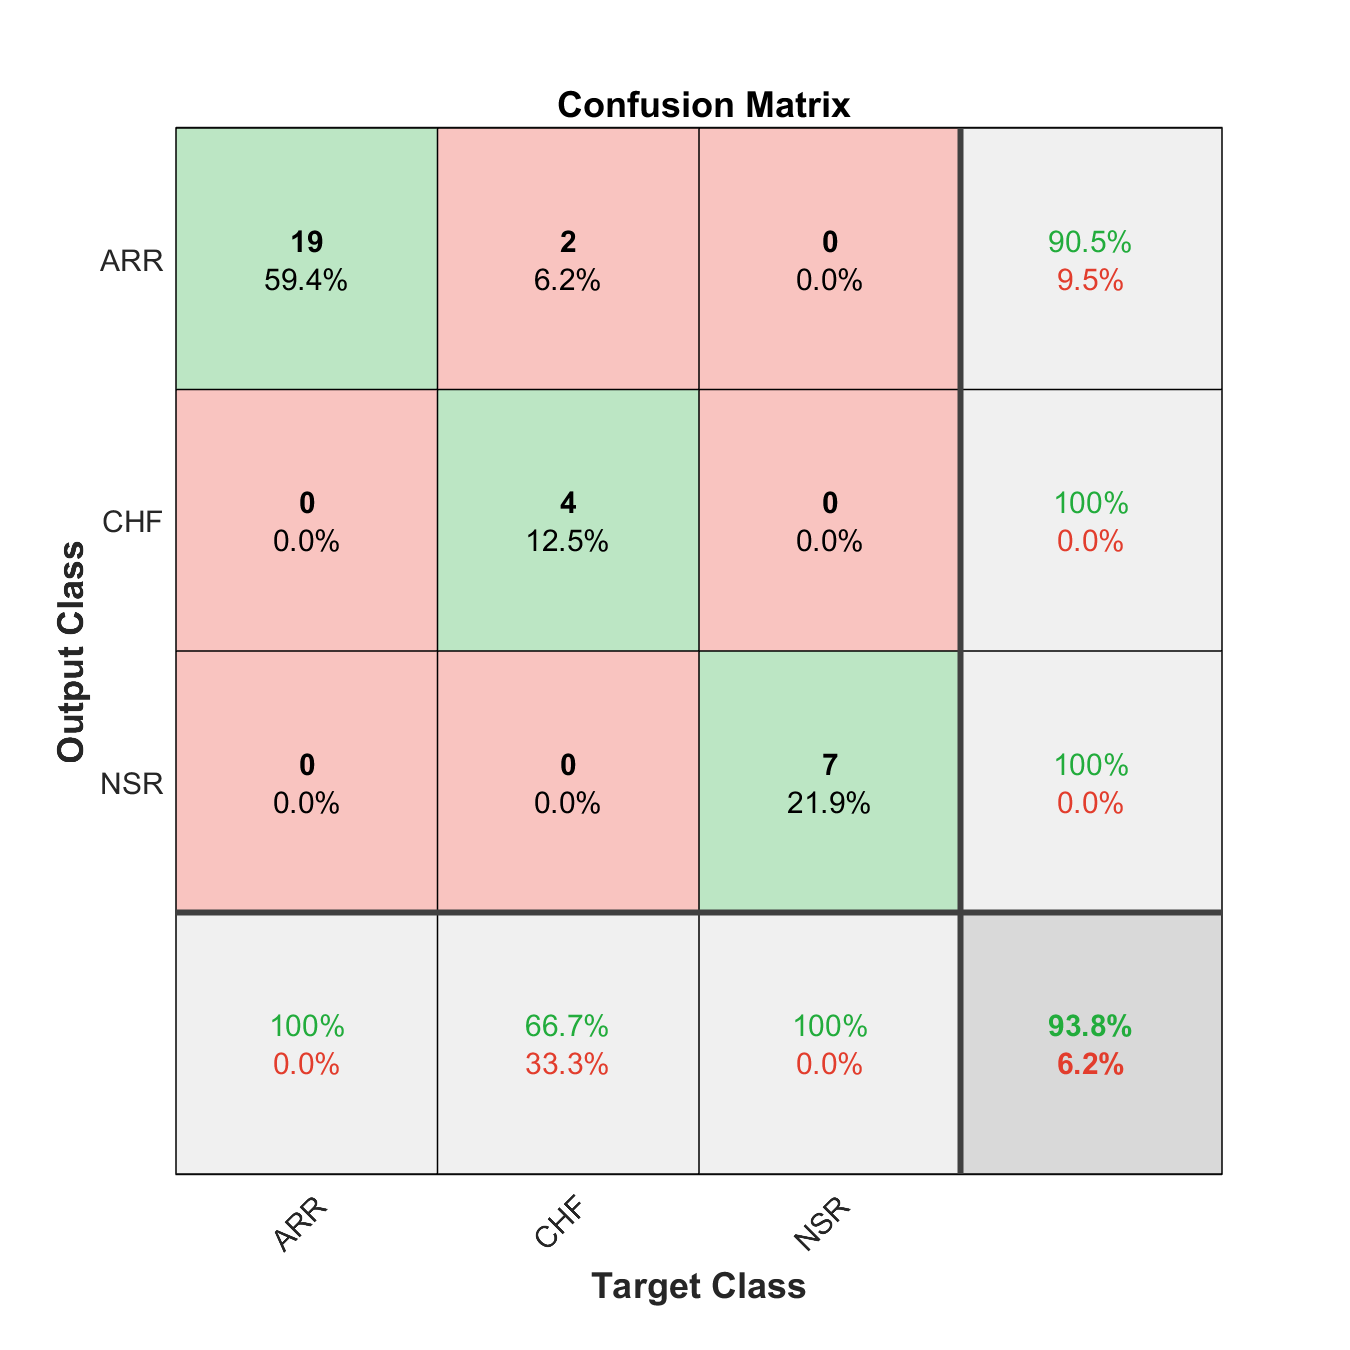

plotconfusion(imgsValidation1.Labels,YPred2)

The confusion matrix shows the relation between the output class and the target class regarding classification and misclassifications. For example, in ARR, we see that out of 21 testing images, 19 are correctly classified, 2 are misclassified as CHF. On the other hand, for CHF and NSR,we could see that all  images are correctly classified.

#### AlexNet Confusion Chart

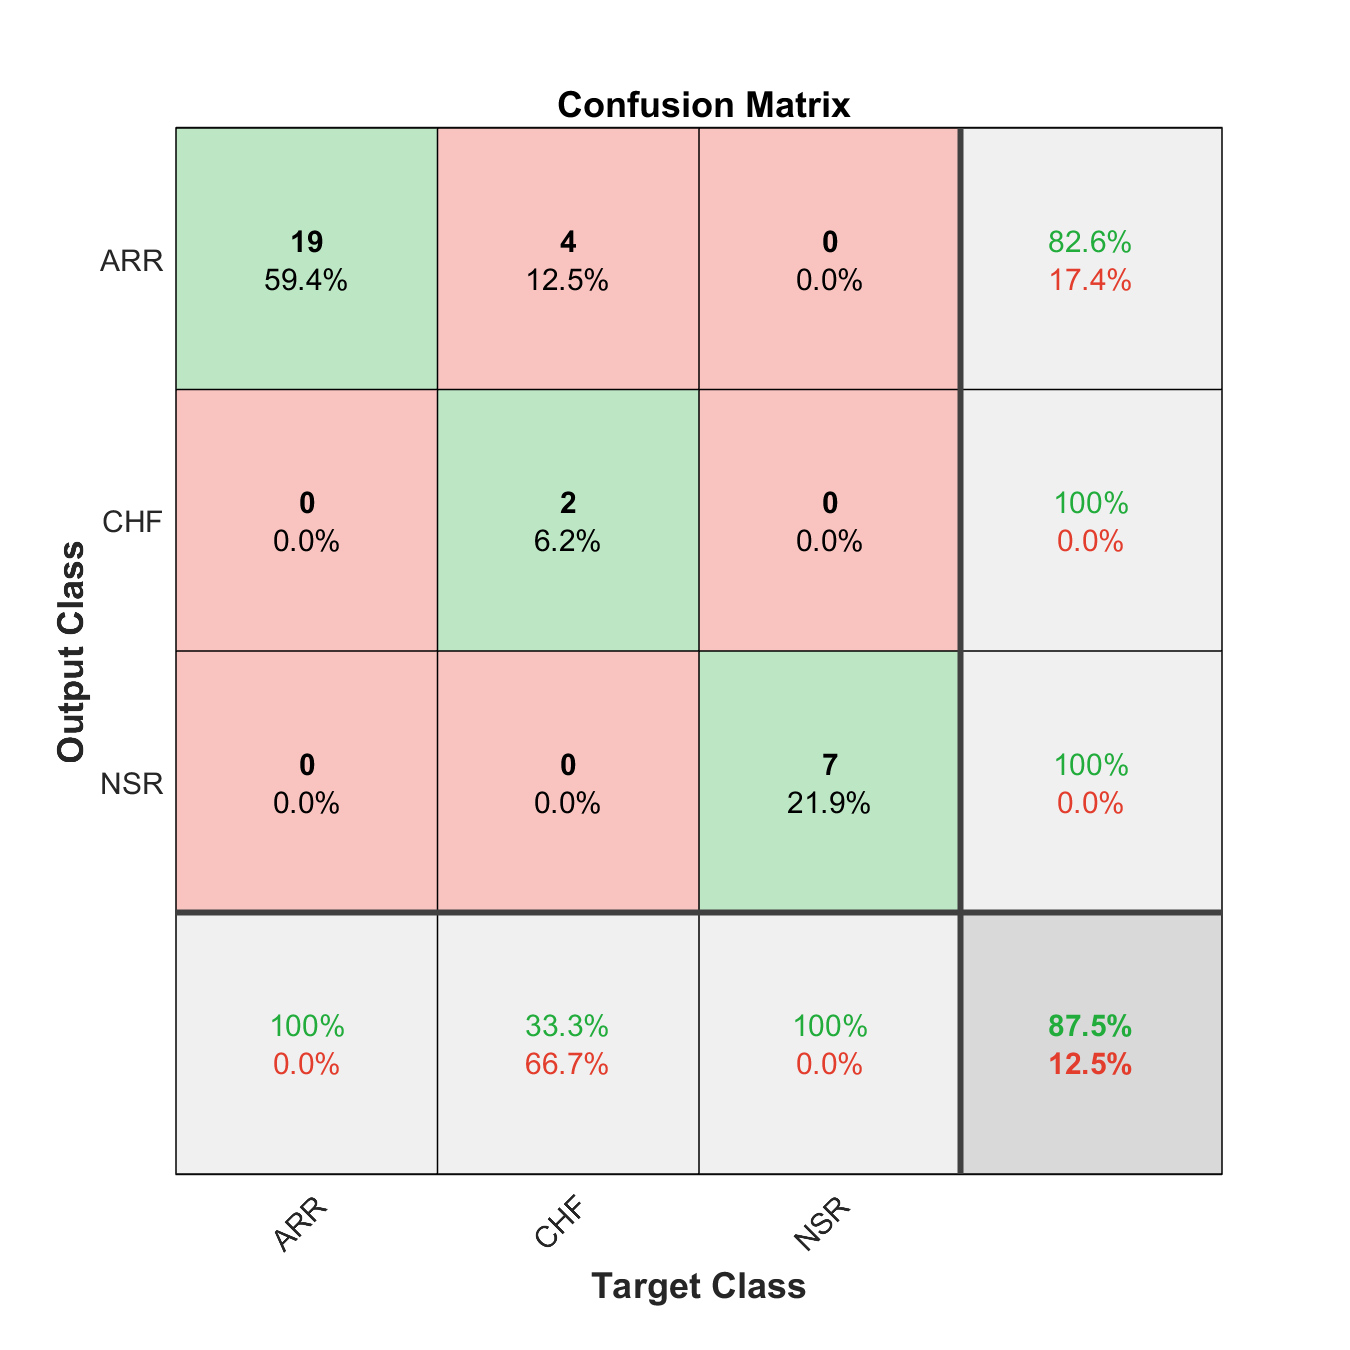

plotconfusion(imgsValidation1.Labels,YPred3)

The confusion matrix shows the relation between the output class and the target class regarding classification and misclassifications. For example, in ARR, we see that out of 23 testing images, 19 are correctly classified, 4 are misclassified as CHF. On the other hand, for CHF and NSR,ws see that all  images are correctly classified.

## Apply the Networks to given ECG Signal

First step we convert the Given Signal Weavlet Transform to a RGB Image:

ecg=load('ecg.mat');
parentDir = tempdir 

parentDir = 'C:\Users\avadh\Desktop\new dsp\'

dataDir = 'data'

dataDir = 'data'

data = ecg.data;


folderpath = strcat('given_signal');

cfs1 = abs(cwt(ecg.data,[],ecg.fs))

cfs1 =     0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0002    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001  


im = ind2rgb(im2uint8(rescale(cfs1)),jet(128));
imwrite(imresize(im,[224 224]),fullfile(folderpath,'Givensignal-WavletTransform.jpg'));

**Reading the Given signal Wavelet (Scelogram) image using**

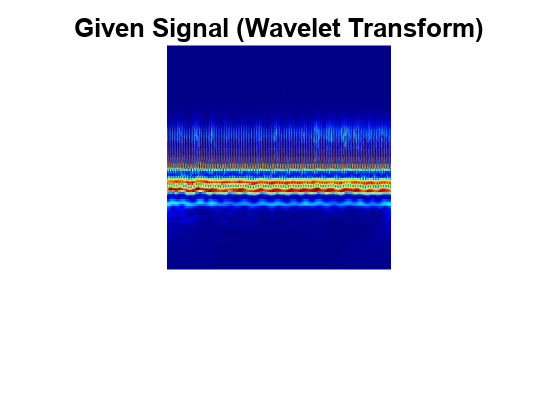

I = imread('C:\Users\avadh\Desktop\new dsp\given_signal\Givensignal-WavletTransform.jpg');
figure
imshow(I)
title('Given Signal (Wavelet Transform)')

## 1-GoogleNet

Checking the Image size becuase the GoogleNet  model requires the image size to be the same as the input size of the network witch is 244.

sizGN = net1.Layers(1).InputSize

sizGN =    224   224     3


Image_size = size(I);
Image_size

Image_size =    224   224     3


**Predict The Given_Signal  by using GoogleNet Network**

labelGN2 = classify(trainedGN,I)

labelGN2 = categorical
     ARR 


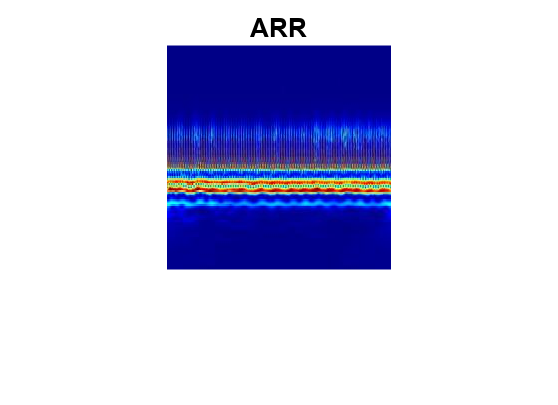

figure
imshow(I)
title(labelGN2)

## 2-SqueezNet

Resize the image to the input size of the SqueezNet network.

sizSQ = net2.Layers(1).InputSize

sizSQ =    227   227     3


I2 = imresize(I,sizSQ(1:2));
Image_size2 = size(I2);
Image_size2

Image_size2 =    227   227     3


**Predict The Given_Signal  by using SqueezNet Network**

labelSQ2= classify(trainedSN,I2)

labelSQ2 = categorical
     NSR 


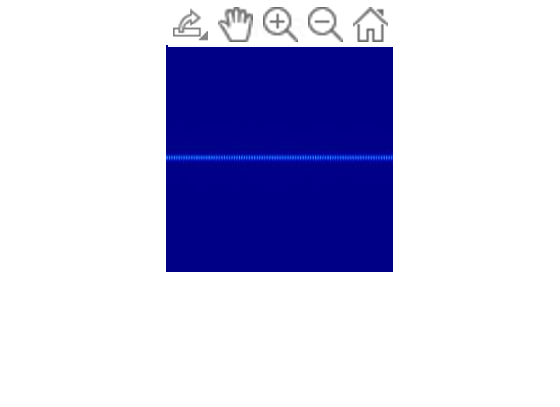

figure
imshow(I2)
title(labelSQ2)

**Predict The Given_Signal  by using AlexNet Network**

labelAL= classify(netTransfer1,I2)

labelAL = categorical
     ARR 


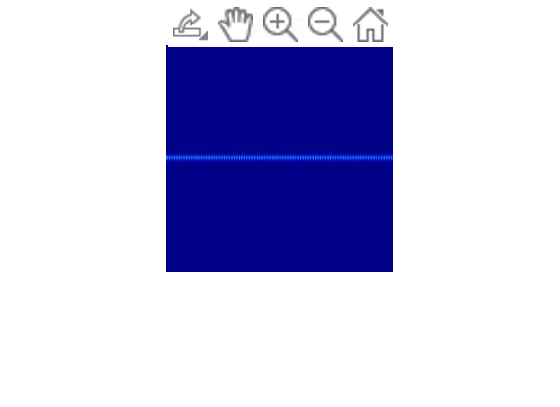

figure
imshow(I2)
title(labelAL)

## Short Time Fourier Transformation Representation Data

## 1-GoogleNet

**1.1Training Options and Train the Network**

Training can be tuned by setting various options. `InitialLearnRate` specifies the initial step size in the direction of the negative gradient of the loss function. `MiniBatchSize` specifies how large of a subset of the training set to use in each iteration. One epoch is a full pass of the training algorithm over the entire training set. `MaxEpochs` specifies the maximum number of epochs to use for training. After trying many values of number of epochs the bast value will that generate good model without overfitting and underfitting will be 10 epochs.

options1 = trainingOptions('sgdm',...
    'MiniBatchSize',10,...
    'MaxEpochs',8,...
    'InitialLearnRate',0.0001,...
    'ValidationData',imgsValidation2,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Train the Network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:18 |       20.00% |       53.12% |       4.2139 |       1.4200 |      1.0000e-04 |
|       1 |          10 |       00:00:50 |       40.00% |       50.00% |       2.1037 |       1.0071 |      1.0000e-04 |
|       2 |          20 |       00:01:19 |       50.00% |       65.62% |       1.6496 |       1.0054 |      1.0000e-04 |
|       3 |          30 |       00:01:47 |       50.00% |       68.75% |       1.0146 |       0.7116 |      1.0000

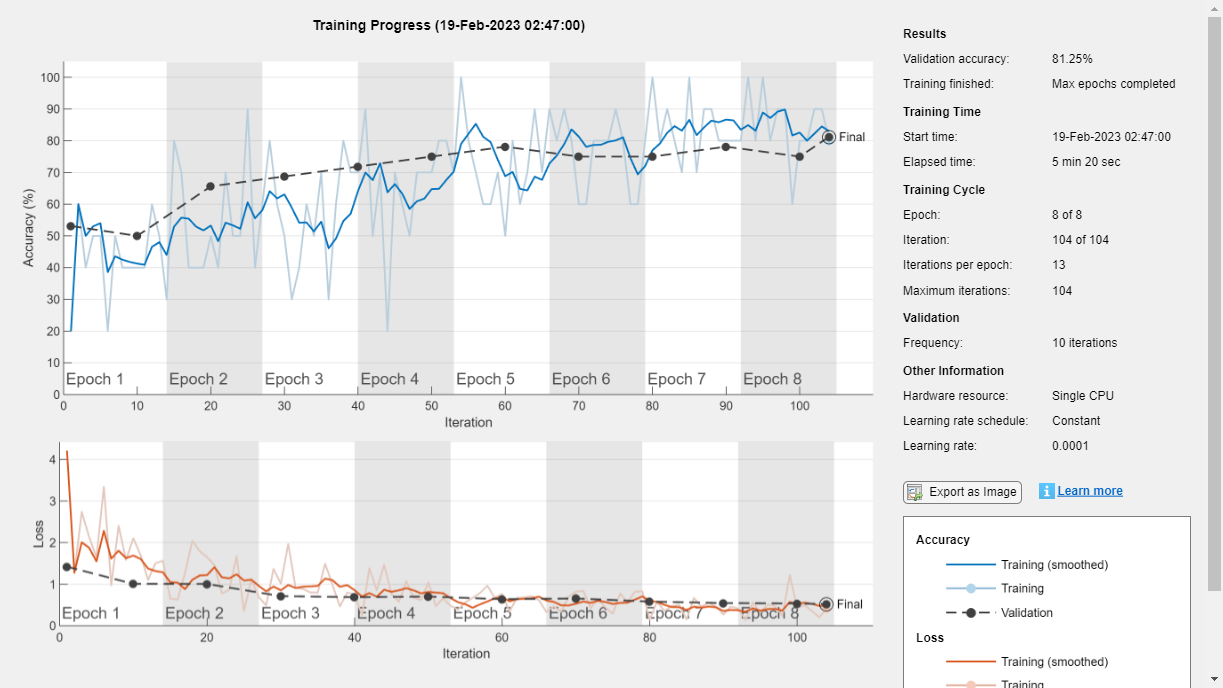

trainedGN2 = trainNetwork(imgsTrain2,lgraphGN,options1);

trainedGN2.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**1.2- Evaluate GoogLeNet **

**1.2.1 Network  Accuracy**

Evaluate the network using the validation data

[YPred1,probs1] = classify(trainedGN2,imgsValidation2);
accuracy = mean(YPred1==imgsValidation2.Labels);
disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%'])

GoogLeNet Accuracy: 81.25%


Display four sample validation images with their predicted labels.

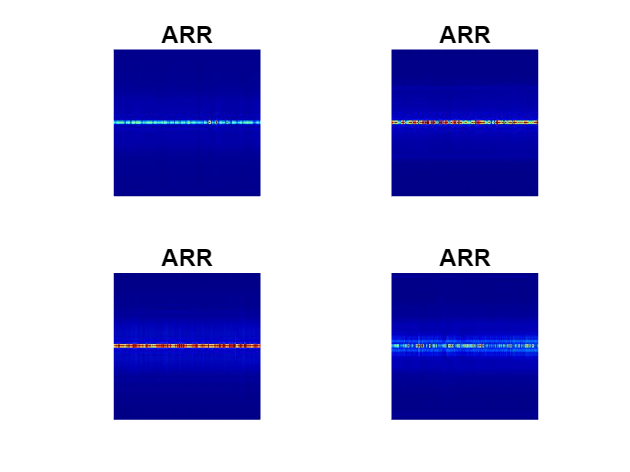

%idx = randperm(numel(imgsValidation.Files),4);
idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation2,idx(i));
    imshow(I)
    label = YPred1(idx(i));
    title(string(label));
end

augimgsTrain2 = augmentedImageDatastore([227 227],imgsTrain2);
augimgsValidation2 = augmentedImageDatastore([227 227],imgsValidation2);

## **2-SqueezeNet**

**2.1 Training Options and Train **

ilr = 3e-4;
miniBatchSize = 10;
maxEpochs = 15;
valFreq = floor(numel(augimgsTrain2.Files)/miniBatchSize);
options2 = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',0.0001,...
    'ValidationData',augimgsValidation2,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default

Train the Network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |       20.00% |       21.88% |       3.0062 |       2.3393 |      1.0000e-04 |
|       1 |          10 |       00:00:25 |       60.00% |       59.38% |       1.0622 |       1.2331 |      1.0000e-04 |
|       2 |          20 |       00:00:39 |       40.00% |       59.38% |       1.0733 |       1.0358 |      1.0000e-04 |
|       3 |          30 |       00:00:53 |       60.00% |       65.62% |       0.9433 |       0.9883 |      1.0000

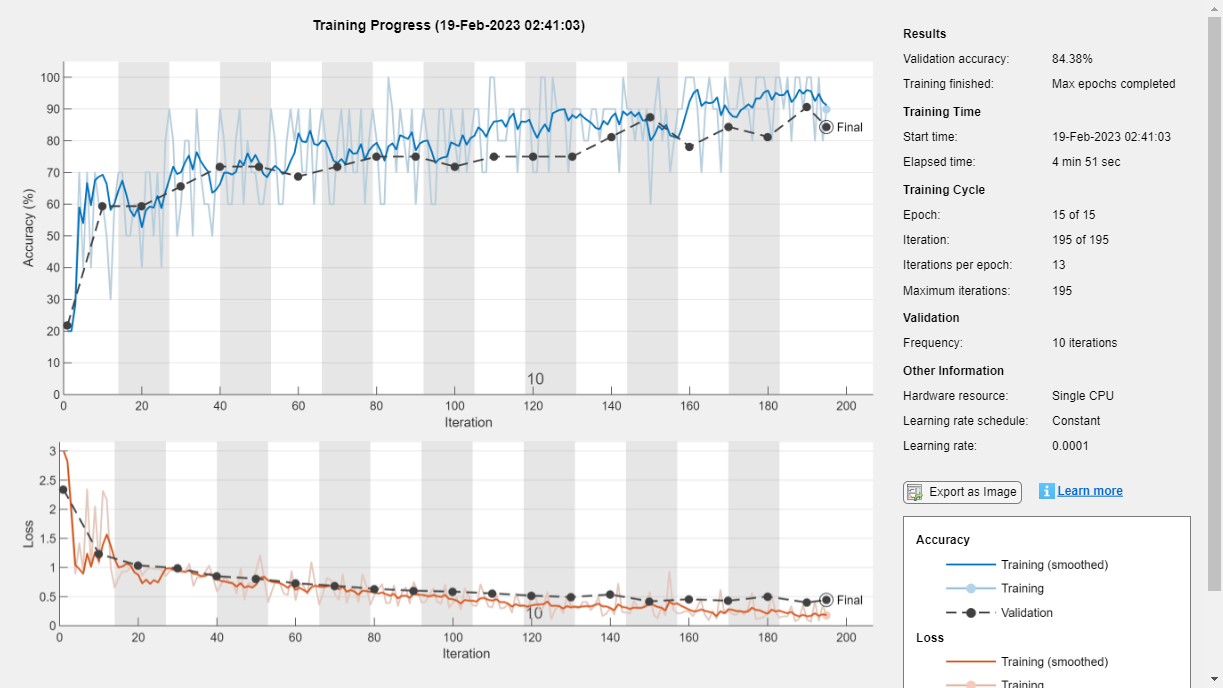

trainedSN2 = trainNetwork(augimgsTrain2,lgraphSqz,options2);

trainedSN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**2.2 Evaluate SqueezeNet Accuracy**

Evaluate the network using the validation data.

[YPred2,probs2] = classify(trainedSN2,augimgsValidation2);
accuracy = mean(YPred2==imgsValidation2.Labels);
disp(['SqueezeNet Accuracy: ',num2str(100*accuracy),'%'])

SqueezeNet Accuracy: 84.375%


Display four sample validation images with their predicted labels

idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation2,idx(i));
    imshow(I)
    label = YPred2(idx(i));
    title(string(label));
end

## 3-AlexNet

**3.1 Training Options and Train AlexNet**

options3 = trainingOptions('sgdm', ...
    'MiniBatchSize',15, ...
    'MaxEpochs',7, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimgsValidation2, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the Network

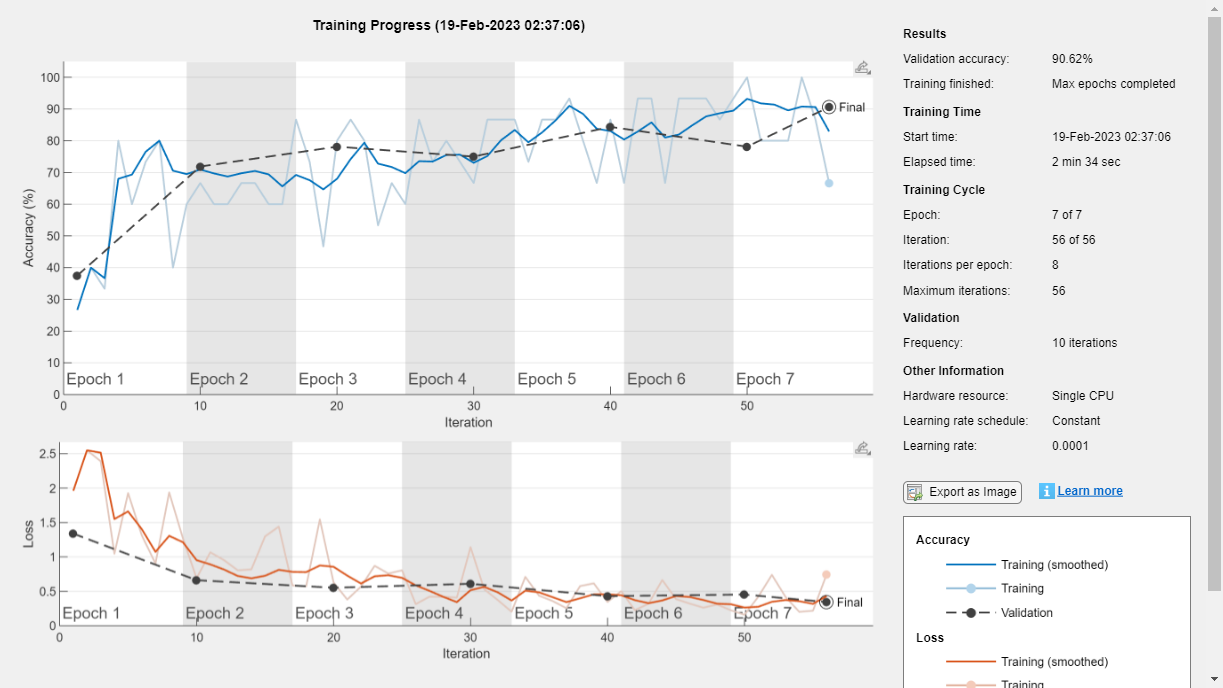

netTransfer2 = trainNetwork(augimgsTrain2,lgraphAlx,options3);

netTransfer2.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


**3.3 Evaluate AlexNet Accuracy**

[YPred3,probs3] = classify(netTransfer2,augimgsValidation2);
accuracy = mean(YPred3==imgsValidation2.Labels);
disp(['ALexNet Accuracy: ',num2str(100*accuracy),'%'])

ALexNet Accuracy: 90.625%


Display four sample validation images with their predicted labels

idx = [11,12,13,9];
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsValidation2,idx(i));
    imshow(I)
    label = YPred3(idx(i));
    title(string(label));
end

## Test and validate the Networks -- Confusion Charts

Compare the results and the reliabilty of the different Time and Frequency Representations and the different Networks. Explain the differences!

## Confusion Charts (Short Time Fourier Transformation Representation)

### GoogleNet Confusion Chart

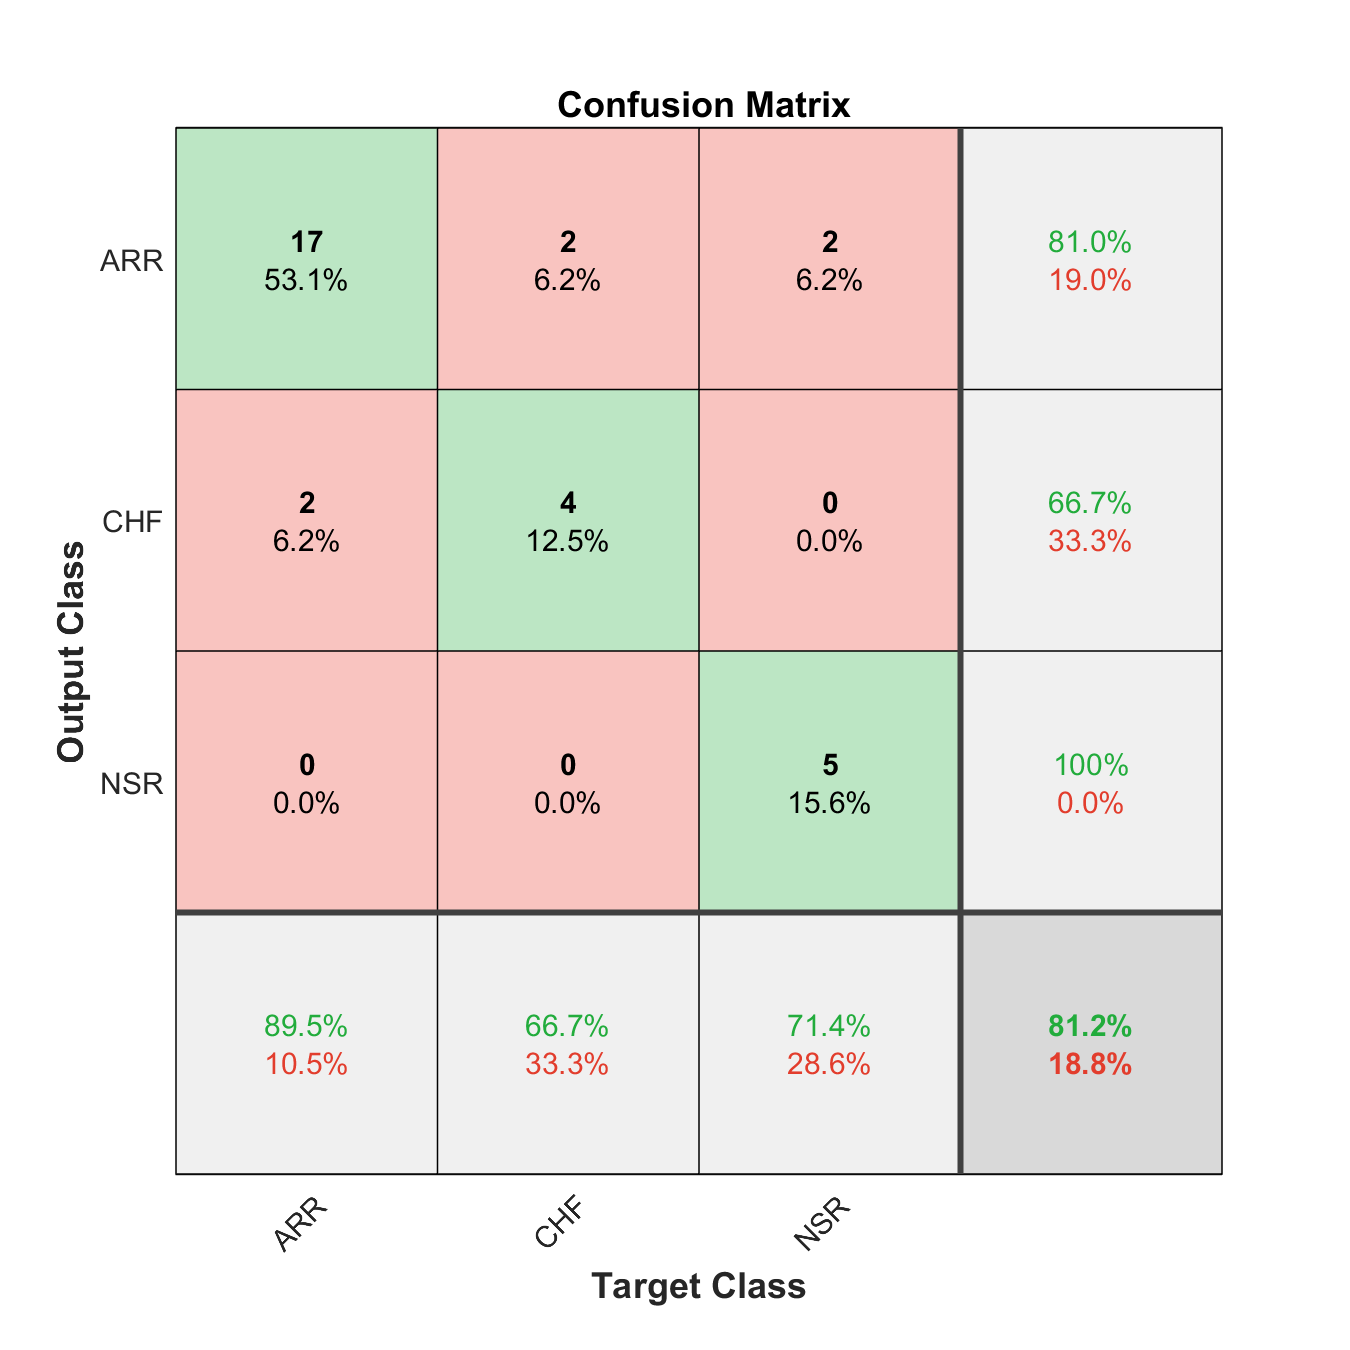

plotconfusion(imgsValidation2.Labels,YPred1)

The confusion matrix shows the relation between the output class and the target class regarding classification and misclassifications. For example, in ARR, we see that out of 21 testing images, 17 are correctly classified, 2 are misclassified as NSR, and 2 as CHF. On the other hand, for CHF we see that out of 6 testing images, 4 are correctly classified, finally in NSR 5 images are correctly classified.

### SqueezNet Confusion Chart

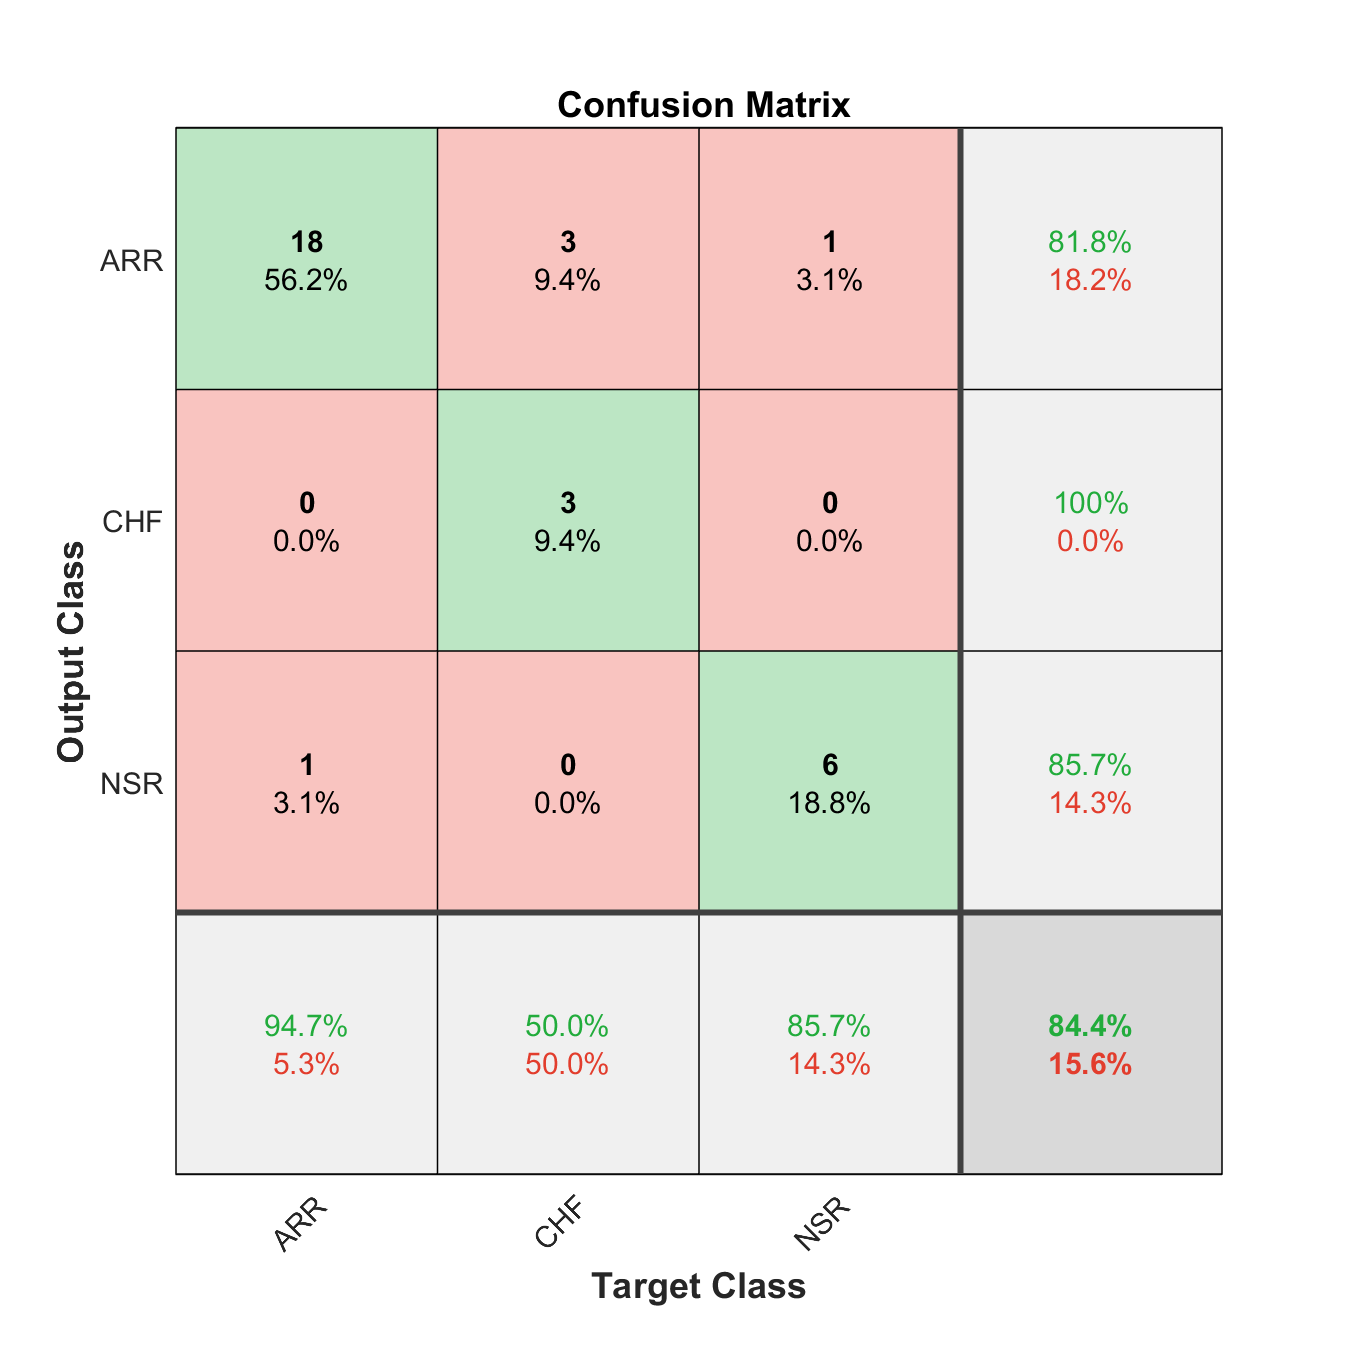

plotconfusion(imgsValidation2.Labels,YPred2)

The confusion matrix shows the relation between the output class and the target class regarding classification and misclassifications. For example, in ARR, we see that out of 22 testing images, 18 are correctly classified, 1 is misclassified as NSR, and 3 as CHF. On the other hand, for CHF we see that out of 3 testing images, 3 are correctly classified finally in  NSR out of 7  images 6  are correctly classified and 1 is misclassified as ARR.

### AlexNet Confusion Chart

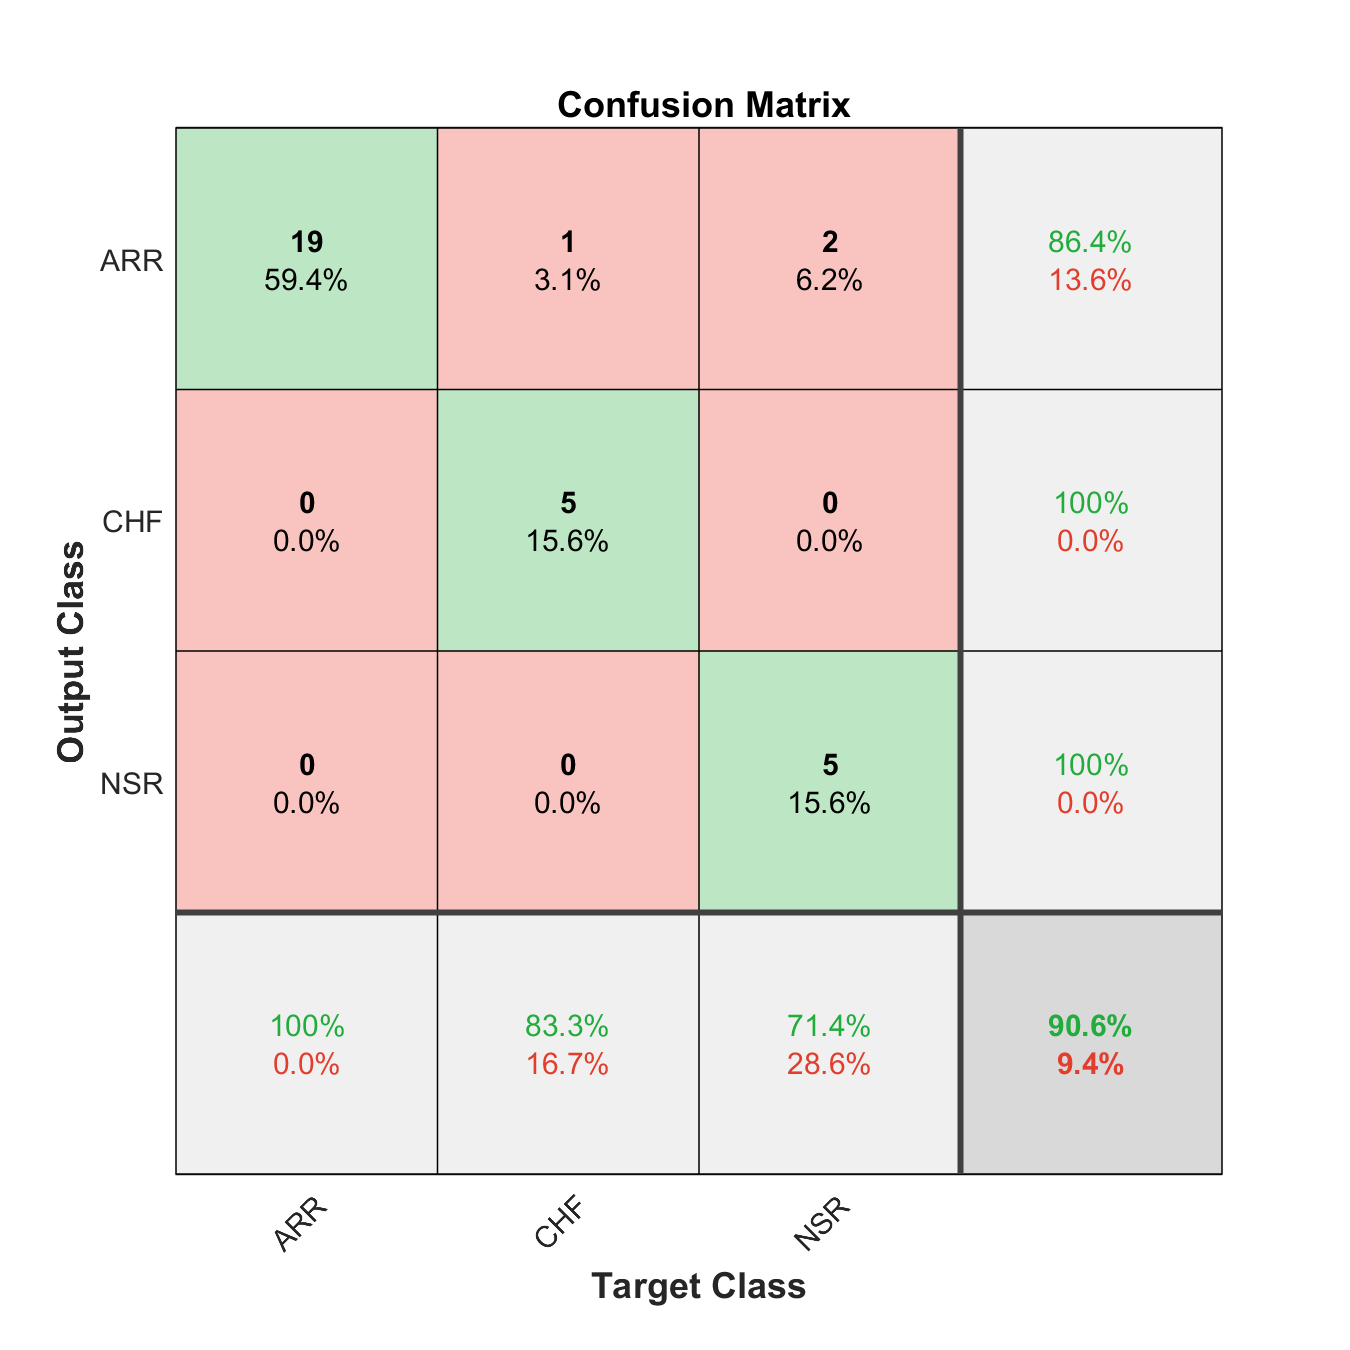

plotconfusion(imgsValidation2.Labels,YPred3)

The confusion matrix shows the relation between the output class and the target class regarding classification and misclassifications. For example, in ARR, we see that out of 22 testing images, 19 are correctly classified, 2 is misclassified as NSR, and 1 as CHF. On the other hand, for CHF we see that out of 5 testing images, 5 are correctly classified and, finally in NSR out of 5 images 5 are correctly classified.

## Apply the Networks to given ECG Signal

First step we convert the Given Signal Weavlet Transform to a RGB Image:

ecg =load('ecg.mat');
y=ecg.data

y =    -0.0506
   -0.0507
   -0.0508
   -0.0508
   -0.0508
   -0.0508
   -0.0510
   -0.0506
   -0.0510
   -0.0506


Fs=ecg.fs

Fs = 8000


folderpath = strcat('given_signal');%put your path here
win = hamming(100,'periodic');
s=stft(y,Fs,'Window',win,'OverlapLength',98,'FFTLength',128);
smag=abs(s);
sphs=angle(s);

im = ind2rgb(im2uint8(rescale(smag)),jet(128));
imwrite(imresize(im,[224 224]),fullfile(folderpath,'given_signal_Spectogram.jpg'));

### Reading the Given signal Wavelet (Scelogram) image using

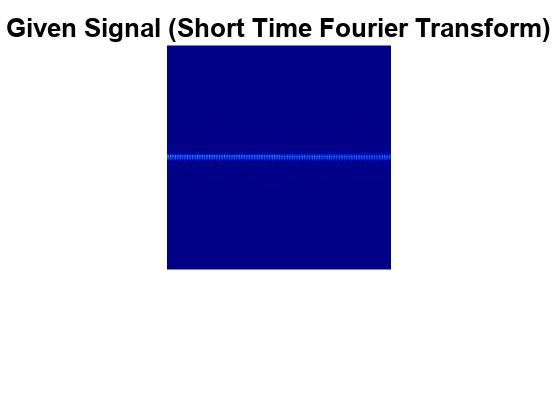

I = imread('C:\Users\avadh\Desktop\new dsp\given_signal\given_signal_Spectogram.jpg');
figure
imshow(I)
title('Given Signal (Short Time Fourier Transform)')

## 1-GoogleNet

Checking the Image size becuase the GoogleNet  model requires the image size to be the same as the input size of the network witch is 244.

sizGN = net1.Layers(1).InputSize

sizGN =    224   224     3


Image_size = size(I);
Image_size

Image_size =    224   224     3


### Predict The Given_Signal  by using GoogleNet Network

%I = imresize(I,sizGN(1:2));
labelGN2 = classify(trainedGN,I)

labelGN2 = categorical
     NSR 


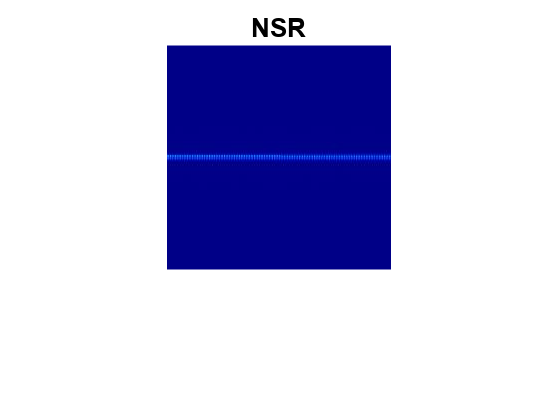

figure
imshow(I)
title(labelGN2)

## 2-SqueezNet

Resize the image to the input size of the SqueezNet network.

sizSQ = net2.Layers(1).InputSize

sizSQ =    227   227     3


I2 = imresize(I,sizSQ(1:2));
Image_size2 = size(I2);
Image_size2

Image_size2 =    227   227     3


### Predict The Given_Signal  by using SqueezNet Network

labelSQ2= classify(trainedSN,I2)

labelSQ2 = categorical
     NSR 


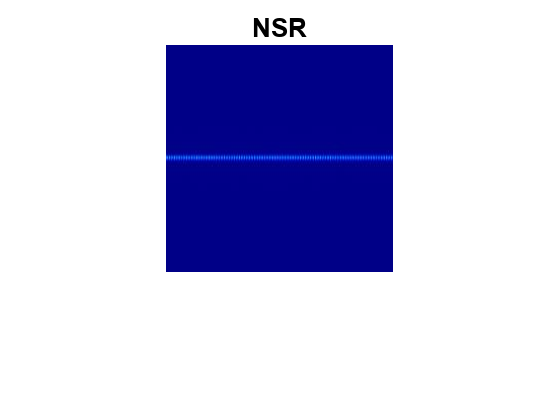

figure
imshow(I2)
title(labelSQ2)

### Predict The Given_Signal  by using AlexNet Network

labelAL= classify(netTransfer2,I2)

labelAL = categorical
     ARR 


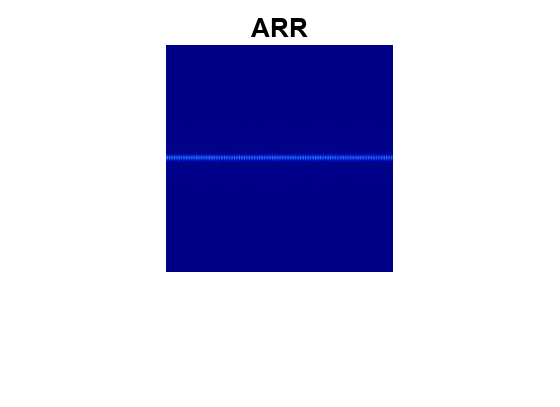

figure
imshow(I2)
title(labelAL)

## Conclusion

To conclude that in this Project we implemented two types of  time-frequency representation using

- Short Time Fourier Transformation and

- Wavelet Transformation

To create Scalograms and spectrograms and insert them as RGB images into three pre-trained CNNs which are GoogleNet, SqeezNet, and AlexNet to Train them and, to classify three types of ECG signals ARR, CHF, and NSR. We could see the results and the accuracy of the tested signals in the CNN that used the scalograms are much better than the CNNs that utilized the spectrograms to train them with an average accuracy of 93% and the most pre-trained CNN that occurs high accuracy is GoogleNet with almost 97% accuracy.

By looking at the result of the prediction of the given signal we can say that the Given Signal is  ARR  ECG type.

### **Supporting Functions**

**1-helperCreateECGDataDirectories** creates a data directory inside a parent directory, then creates three subdirectories inside the data directory. The subdirectories are named after each class of ECG signal found in `ECGData`.

function helperCreateECGDirectories(ECGData,parentFolder,dataFolder)


rootFolder = parentFolder;
localFolder = dataFolder;
mkdir(fullfile(rootFolder,localFolder))

folderLabels = unique(ECGData.Labels);
for i = 1:numel(folderLabels)
    mkdir(fullfile(rootFolder,localFolder,char(folderLabels(i))));
end
end

**2-helperPlotReps** plots the first thousand samples of a representative of each class of ECG signal found in `ECGData`.

function helperPlotReps(ECGData)


folderLabels = unique(ECGData.Labels);

for k=1:3
    ecgType = folderLabels{k};
    ind = find(ismember(ECGData.Labels,ecgType));
    subplot(3,1,k)
    plot(ECGData.Data(ind(1),1:1000));
    grid on
    title(ecgType)
end
end

**3-helperCreateRGBfromTF** uses [`cwtfilterbank`](https://de.mathworks.com/help/wavelet/ref/cwtfilterbank.html) to obtain the continuous wavelet transform of the ECG signals and generates the scalograms from the wavelet coefficients. The helper function resizes the scalograms and writes them to disk as jpeg images.

function helperCreateRGBfromTF(ECGData,parentFolder,childFolder)


imageRoot = fullfile(parentFolder,childFolder);

data = ECGData.Data;
labels = ECGData.Labels;

[~,signalLength] = size(data);

fb = cwtfilterbank('SignalLength',signalLength,'VoicesPerOctave',12);
r = size(data,1);

for ii = 1:r
    cfs = abs(fb.wt(data(ii,:)));
    im = ind2rgb(im2uint8(rescale(cfs)),jet(128));
    imgLoc = fullfile(imageRoot,char(labels(ii)));
    imFileName = strcat(char(labels(ii)),'_',num2str(ii),'.jpg');
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
end
end

**4-helperCreateRGBfromSTF**

function helperCreateRGBfromSTF(ECGData,parentFolder,childFolder)
imageRoot = fullfile(parentFolder,childFolder);
data = ECGData.Data;
labels = ECGData.Labels;

Fs=126;

win = hamming(100,'periodic');


r = size(data,1);

for ii = 1:r
    

    s=stft((data(ii,:)),Fs,'Window',win,'OverlapLength',98,'FFTLength',128);
    %s=stft((data(ii,:)),Fs,'Window',wind,'OverlapLength',olen,'FFTLength',nfft);
    smag=abs(s);
    sphs=angle(s);
    im = ind2rgb(im2uint8(rescale(smag)),jet(128));
    imgLoc = fullfile(imageRoot,char(labels(ii)));
    imFileName = strcat(char(labels(ii)),'_',num2str(ii),'.jpg');
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName))
end
end